**Traitement des données cinématiques sujets sains (ANALYTIC)**

Contexte : analyse des données des tâches motrices **de mouvements** sur 3 angles de l'épaule lors de différentes actions : 

- ANALYTIC1 : flexion (élévation sagittale)

- ANALYTIC2 : abduction (élévation coronale)

- ANALYTIC3 : rotation externe (abduction 0°)

- ANALYTIC4 : rotation interne (abduction 0°)

- ANALYTIC5 : élévation dans le plan scapulaire (uniquement chez les sujets sains)

**Analyse des angles (S1)**

**Utilisation des données traitées avec la matrice .mat à comparer avec notre traitement cinématique**

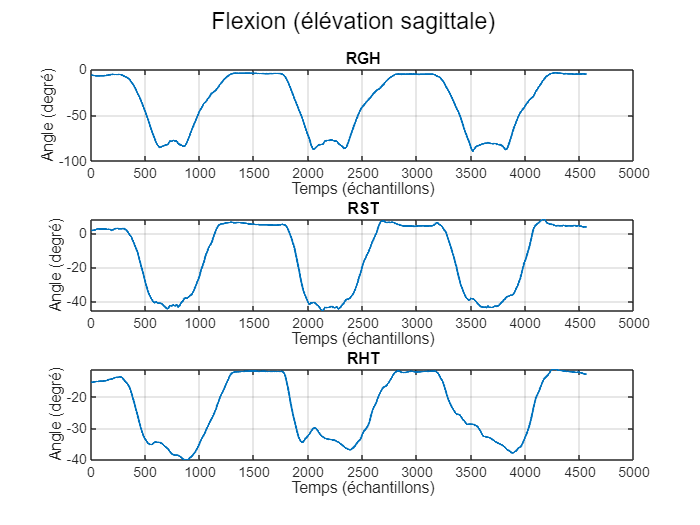

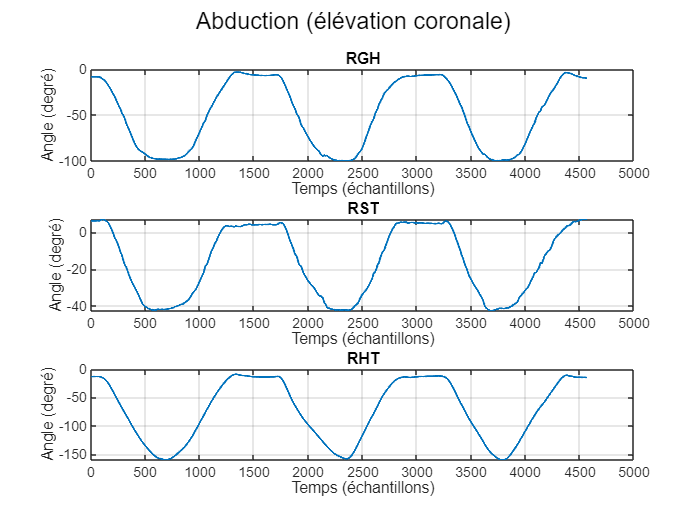

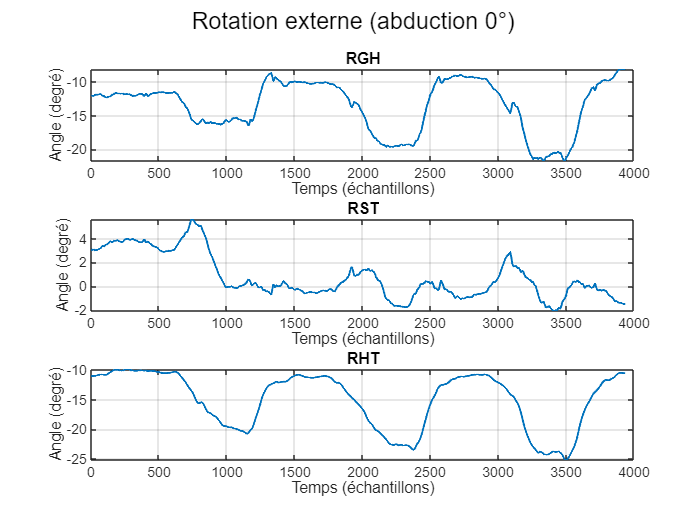

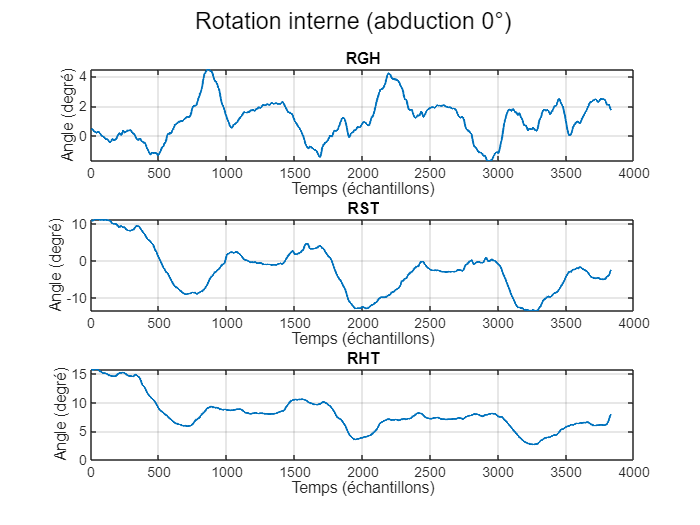

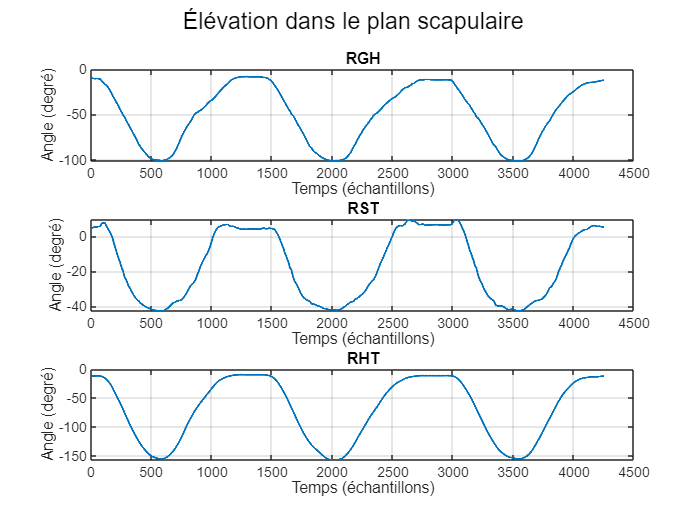

clc; clear all; 

% Fichiers MAT  
matFiles = {...  
    'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\MF01\MF01-MF01-20240101-20240710.mat', ...
};

% Définition des analytics (ANALYTIC1 à ANALYTIC5) avec leurs descriptions
nb_analytics = 5;
analytic_indices = 4:8;
analytic_labels = {... 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)', ...
    'Élévation dans le plan scapulaire'};

% Liste des 6 articulations contenant des données
joints = {'RGH', 'RST','RHT'};
nb_joints = length(joints);

% Boucle sur chaque sujet
for subj_idx = 1:length(matFiles)
    % Charger les données du sujet
    base = load(matFiles{subj_idx});
    data = base.Trial;

    % Boucle sur chaque analytic
    for a_idx = 1:nb_analytics
        analytic_data = data(analytic_indices(a_idx));
        joint_data = analytic_data.Joint; % Toutes les articulations disponibles

        figure;
        sgtitle(sprintf(' %s',analytic_labels{a_idx})); % Titre général de la figure

        for i = 1:nb_joints
            joint_name = joints{i}; % Nom de l'articulation

            % Trouver l'indice correspondant dans joint_data
            joint_idx = find(strcmp({joint_data.label}, joint_name));

            if isempty(joint_idx)
                warning(['Articulation ', joint_name, ' non trouvée dans joint_data']);
                continue;
            end

            % Vérification de la structure des données
            if isfield(joint_data(joint_idx), 'Euler') && isfield(joint_data(joint_idx).Euler, 'full')
                euler_data = joint_data(joint_idx).Euler.full;
                dims = size(euler_data);

                % Vérification de la structure (1x3xN)
                if dims(1) == 1 && dims(2) == 3 && dims(3) > 1
                    angle_index = 1; % 1 = Flexion, 2 = Abduction, 3 = Rotation

                    % Extraction de l'angle temporel
                    kin = squeeze(euler_data(1, angle_index, :));
                    time_original = 1:length(kin); % Utilisation du temps natif

                    % Création du subplot pour chaque articulation (affichage vertical)
                    subplot(nb_joints, 1, i);
                    plot(time_original, kin, 'LineWidth', 1.2);
                    title(joint_name);
                    xlabel('Temps (échantillons)'); 
                    ylabel('Angle (degré)');
                    grid on;
                else
                    warning(['Format inattendu pour Euler.full dans ', joint_name]);
                end
            else
                warning(['Euler.full non trouvé pour ', joint_name]);
            end
        end
    end
end